# Enzyme kinetics within our GRASP: A computational platform for building kinetic models of cellular metabolism

**Marta R. A. Matos, Pedro A. Saa, Nicholas Cowie, Svetlana Volkova, Marina de Leeuw, Lars K. Nielsen**

The aim of this tutorial is to illustrate the execution and use of GRASP for building and analyzing kinetic models of metabolism. This tutorial demonstrates how to build an ensemble of models consistent with experimental data. A kinetic model of the mammalian methionine cycle is used for illustration purposes (Saa and Nielsen, 2016). 

### 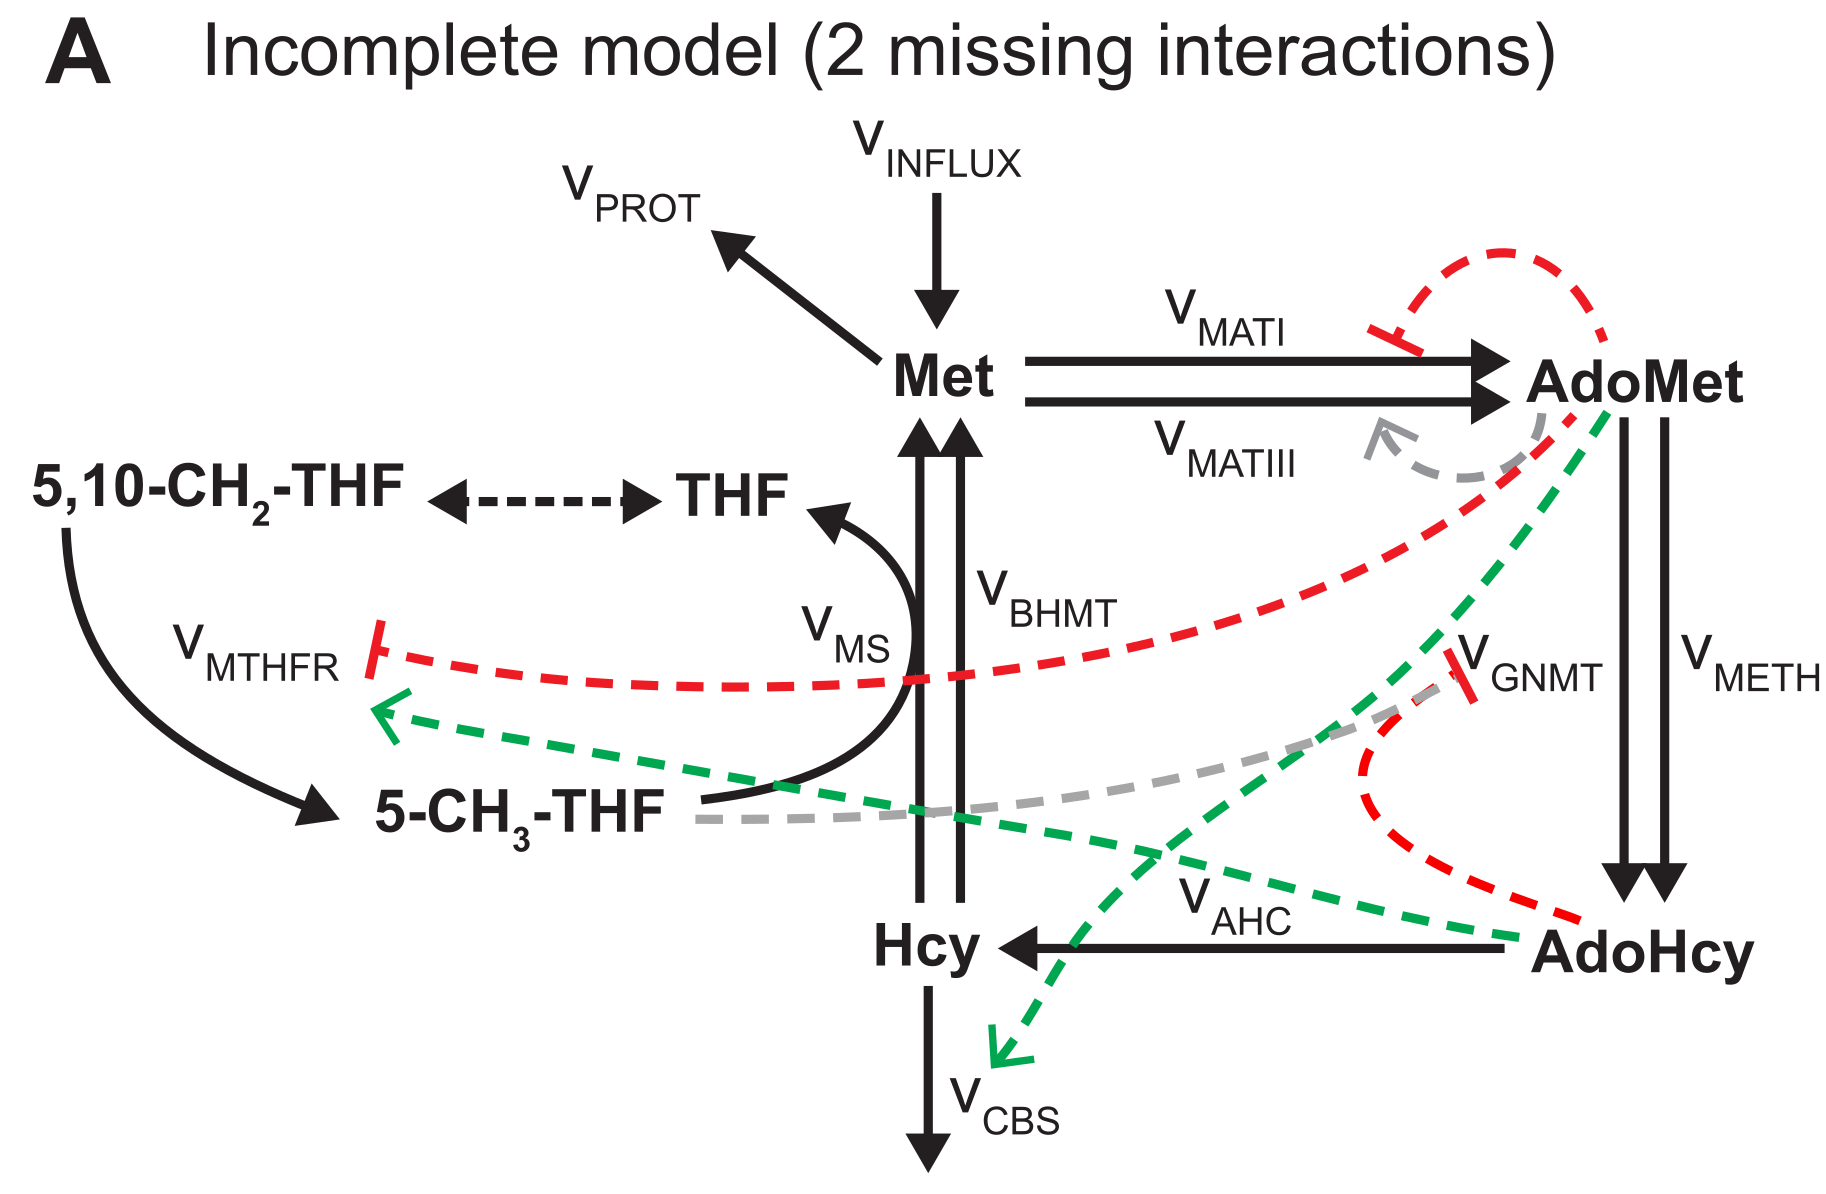    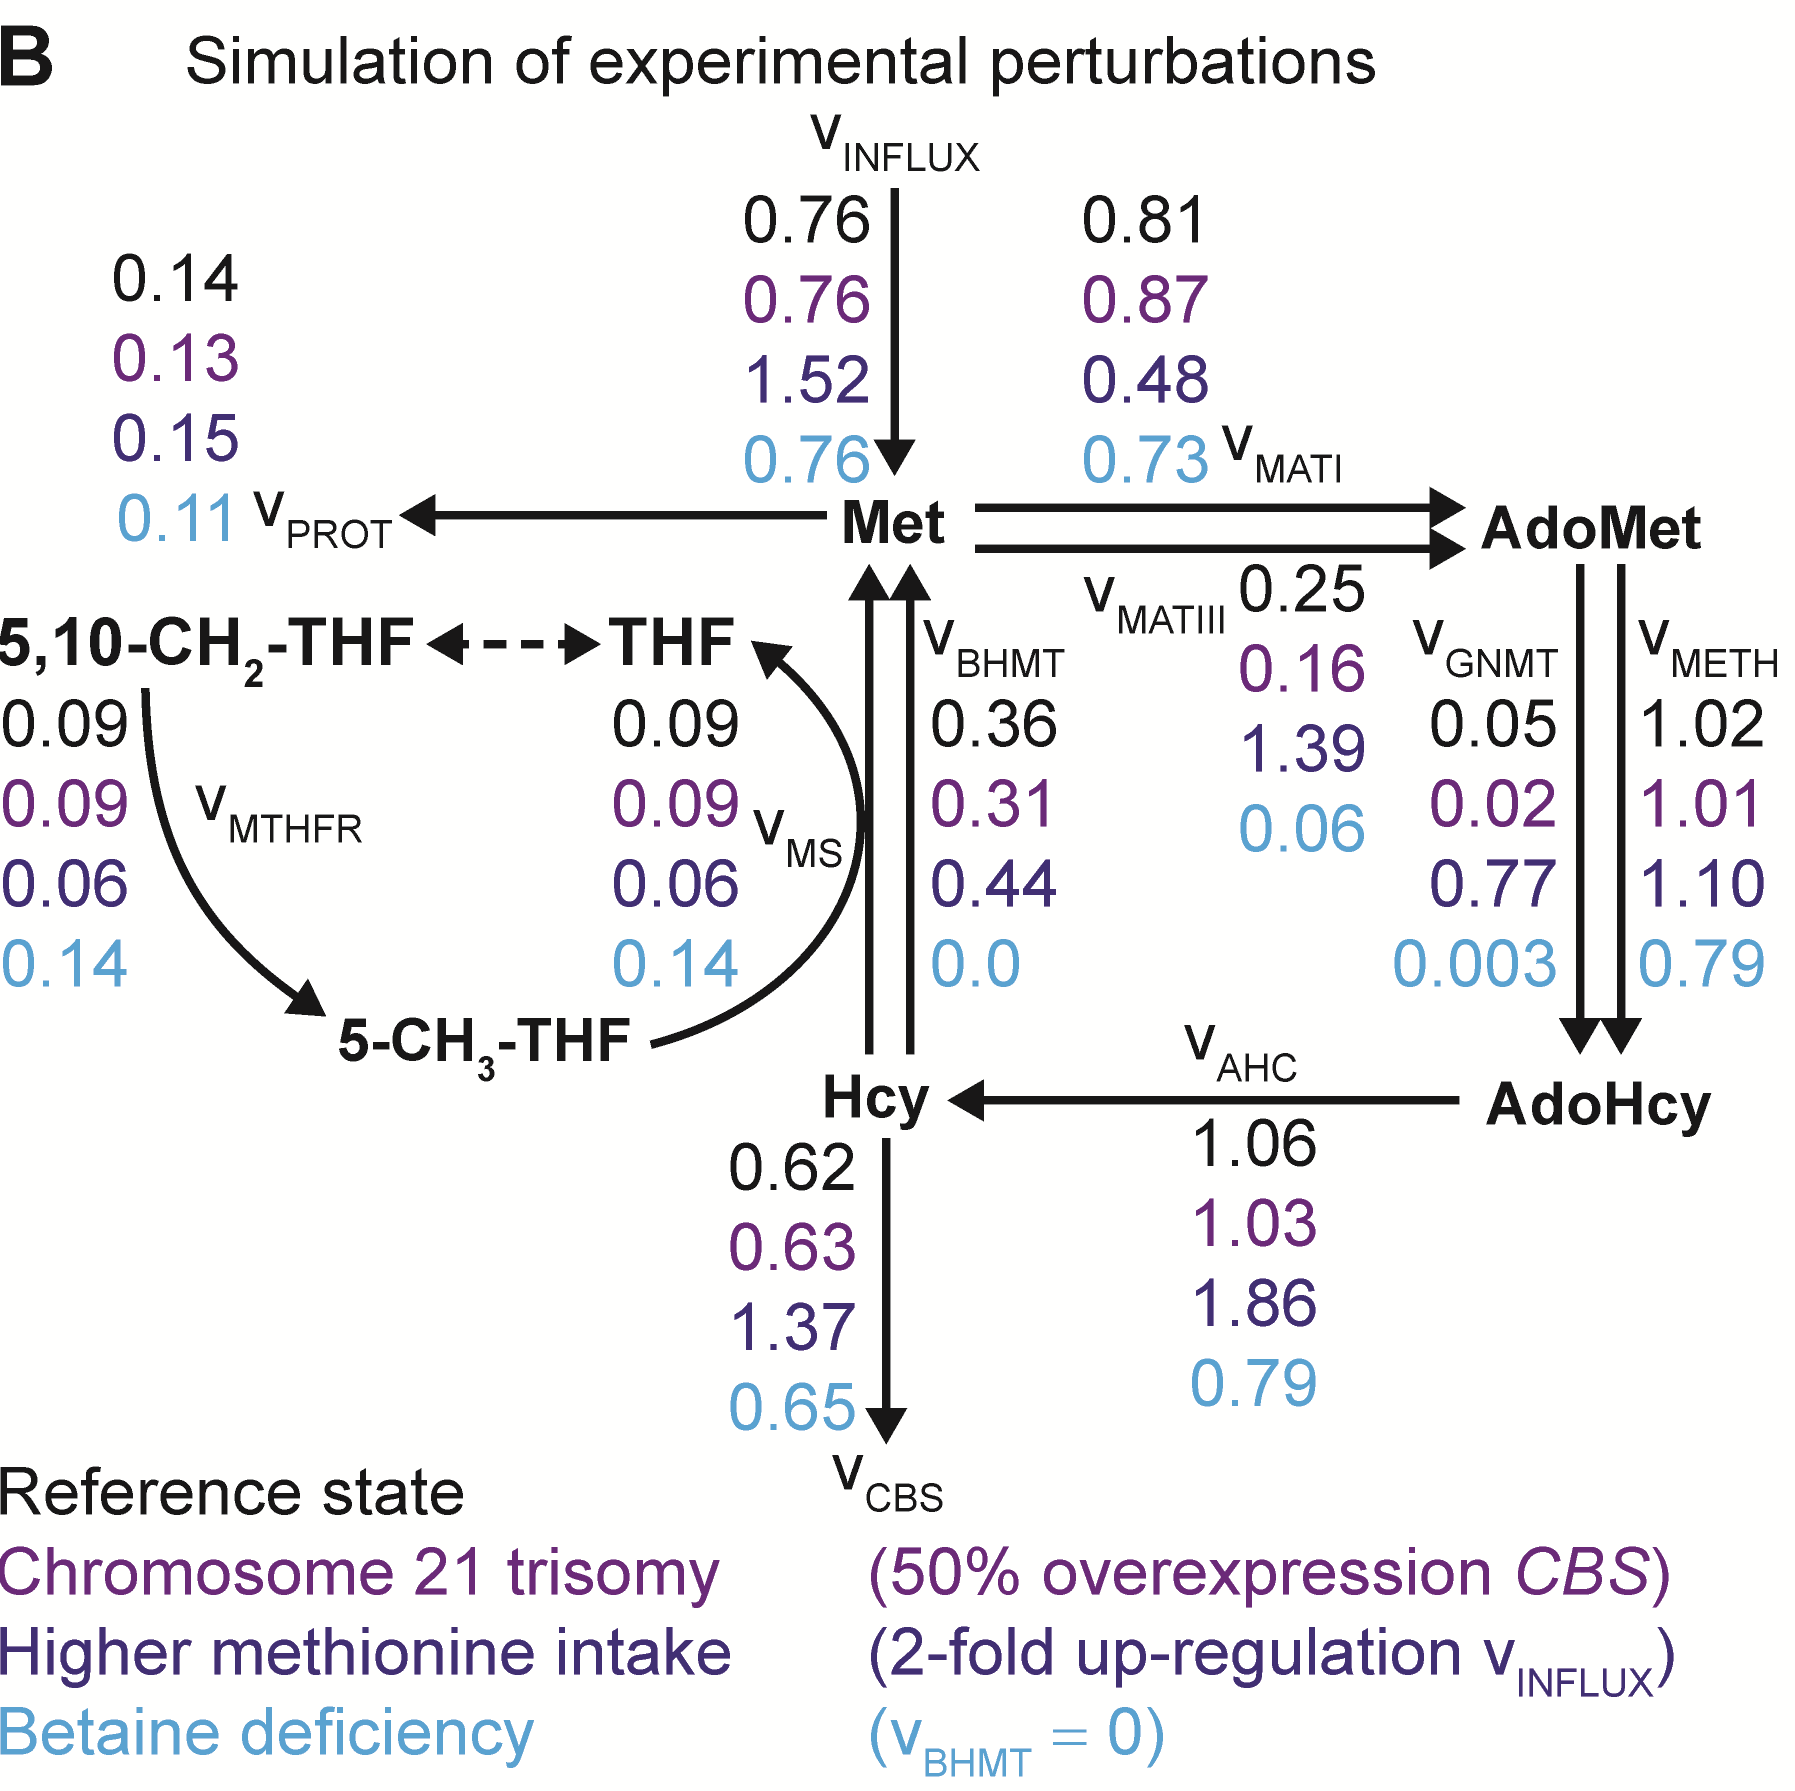

**Figure 1.** Scheme of the mammalian methionine cycle and possible missing interactions (**A**). In this case, two regulatory interactions were removed from the model. The model with all and without the two interactions were fitted and evaluated for Bayesian model selection. (**B**) Illustrative perturbation dataset employed for fitting the kinetic model and perform model selection. In this particular example, the first and third perturbation datasets were used to train the models.

## Tutorial 04: Model selection and fitting of kinetic models consistent with experimental data (rejection mode)

Clear all variables and add functions to path.  Note that you need to be in the tutorials folder.

clear, close all
rng('default');                 % for reproducibility
addpath(fullfile('..', 'matlab_code', 'analysisFxns'), ...
        fullfile('..', 'matlab_code', 'ensembleFxns'), ...
        fullfile('..', 'matlab_code', 'patternFxns'));

Set the maximum number of models to sample. This is particularly important when simulating the model from the prior (i.e., no experimental data defined)

maxNumberOfSamples = 1e5;

Set a threshold for the minimum Jacobian eigenvalue of the system. Models with values below this threshold will be discarded due to unstability criteria.

eigThreshold = 1e-5;

Define the model ID name, input and output files. These paths are necessary for executing GRASP.

modelID = 'tutorial_04_methionine_cycle';
inputFile  = fullfile('..', 'io', 'input', modelID);
outputFile = fullfile('..', 'io', 'output', [modelID, '.mat']);

Build the kinetic ensemble. In this case, we will build an ensemble of 16 models. These models will have a max. flux discrepancy of 40% (0.4 in the specification sheet) for the experimental conditions. To accelerate the execution of the sampler, we will use the parallel mode with 2 cores assigned.

tic
ensemble = buildEnsemble(inputFile, outputFile, maxNumberOfSamples, eigThreshold);

General information loaded.
Flux data computed and loaded.
The fluxes and Gibbs energies are consistent.
Flux directions are consistent.
Gibbs energy directions are consistent.
The initial point obtained from TMFA is feasible and valid for starting the sampler.
Thermodynamic data computed and loaded.
Metabolomics data loaded.
No previous prior for model 1
Proteomics and exchange data loaded and consistent.
Kinetic information loaded and kinetic model built: Structure 1.
No previous prior for model 2
Kinetic information loaded and kinetic model built: Structure 2.
Ensemble structure ready.
Ensemble successfully initialized.
Sampling fluxes


Error using parpool (line 113)
Found an interactive session. You cannot have multiple interactive sessions open simultaneously. To terminate the existing session, use 'delete(gcp('nocreate'))'.

Error in sampleFluxesAndGibbsFreeEnergies (line 41)
    parpool(ensemble.numCores);                 % Run one Markov cha

toc

We can determine the most likely model by inspecting the ABC-posterior distribution. The following chart and simple calculation demonstrate that the complete model is far superior than the incomplete model.

pie([sum(ensemble.populations.strucIdx==1),sum(ensemble.populations.strucIdx==2)],{'complete model','incomplete model'});
prob_completeModel = sum(ensemble.populations.strucIdx==1)/numel(ensemble.populations.strucIdx)
prob_incompleteModel = sum(ensemble.populations.strucIdx==2)/numel(ensemble.populations.strucIdx)

## References

- Saa PA, Nielsen LK (2016). Construction of feasible and accurate kinetic models of metabolism: A Bayesian approach. Scientific Reports **6**: 29635.